# MK10 Tire Review Script

%=============================================
% MK10 Tire Review Script
% Authors: Rohan Shinde || Jenna Lacuata
% Functions
    % Determine Testing Cases (3)
    % Calculate Tire Forces and Moments using MFeval and .tir files
    % Plot Lateral and Longitudinal Graphs with Additional Formatting
    % Calculate peaks, slopes, behaviour of plots

% For Questions -> Rohan Shinde
%=============================================

## Array & Parameter Extraction

% INSTRUCTIONS:
% -> Try not to change P1 (we chose 12PSI as a test pressure)
% -> Add additional params by extracting correct column from output (check Notion for column info)
% -> Make all calculations here (be sure to change index for each tire)

addpath('VD10_TIR_001_MkXTireReview_MFeval.mlx');


%tire 1
[output1, output2, output3, output4]  = VD11_MFeval_TIR_File_Parser(".\tirFiles\magicformula_R20.tir");

%tire 2
[output1, output2, output3, output4]  = VD11_MFeval_TIR_File_Parser(".\tirFiles\magicformula_LC0.tir");


[ Fz1, Fz2, Fz3, Fz4, kappa, alpha, gamma, phit, Vx, P ] = VD_11_Constants();

P1 = P(1,1);                            % Pressure value used in title of graph (12PSI)

% 1
Fx1 = output1(:,1).*0.224809;           % Longitudinal Force
                                        % 1 N = 0.224809 lbf (Used multiple times below)
Fy1 = output1(:,2).*0.224809;           % Lateral Force
                                        % 1 N = 0.224809 lbf (Used multiple times below)
Mz1 = output1(:,6);                     % Self-Aligning Moment
Mx1 = output1(:,4);                     % Overturning Moment
LS1 = output1(:,7);                     % Longitudinal SLip
                                        % Convert to degrees
SA1 = rad2deg(output1(:,8));            % Slip Angle
                                        % Convert to degrees
t1 = output1(:,16);                     % Pnuematic Trail
mux1 = output1(:,17);                   % Longitudinal Friction Coefficient
muy1 = output1(:,18);                   % Lateral Friction Coefficient
ICS1 = output1(:,29);                   % Instantaneous cornering stiffness
Fz1_0 = Fz1(1,1).*0.224809;             % Normal Force used in legend
Kya1 = output1(:,26).*0.224809;         % Cornering Stiffness
mu_lat1 = abs(Fy1)./Fz1_0;              % Lateral coeff of friction for diff slip angles
mu_long1 = abs(Fx1)./Fz1_0;             % Long coeff of friction for diff slip angles

% F2
Fx2 = output2(:,1).*0.224809;
Fy2 = output2(:,2).*0.224809;
Mz2 = output2(:,6);
Mx2 = output2(:,4);
LS2 = output2(:,7);
SA2 = rad2deg(output2(:,8)); 
t2 = output2(:,16);
mux2 = output2(:,17);
muy2 = output2(:,18);
ICS2 = output2(:,29);
Fz2_0 = Fz2(1,1).*0.224809;
Kya2 = output2(:,26).*0.224809;
mu_lat2 = abs(Fy2)./Fz2_0; 
mu_long2 = abs(Fx2)./Fz2_0; 

% F3
Fx3 = output3(:,1).*0.224809;
Fy3 = output3(:,2).*0.224809;
Mz3 = output3(:,6);
Mx3 = output3(:,4);
LS3 = output3(:,7);
SA3 = rad2deg(output3(:,8)); 
t3 = output3(:,16);
mux3 = output3(:,17);
muy3 = output3(:,18);
ICS3 = output3(:,29);
Fz3_0 = Fz3(1,1).*0.224809;
Kya3 = output3(:,26).*0.224809;
mu_lat3 = abs(Fy3)./Fz3_0; 
mu_long3 = abs(Fx3)./Fz3_0; 

% F4
Fx4 = output4(:,1).*0.224809;
Fy4 = output4(:,2).*0.224809;
Mz4 = output4(:,6);
Mx4 = output4(:,4);
LS4 = output4(:,7);
SA4 = rad2deg(output4(:,8)); 
t4 = output4(:,16);
mux4 = output4(:,17);
muy4 = output4(:,18);
ICS4 = output4(:,29);
Fz4_0 = Fz4(1,1).*0.224809;
Kya4 = output4(:,26).*0.224809;
mu_lat4 = abs(Fy4)./Fz4_0; 
mu_long4 = abs(Fx4)./Fz4_0; 

[max_Fy1, index1] = max(Fy1);
max_SA1 = SA1(index1);
[max_Fy2, index2] = max(Fy2);
max_SA2 = SA2(index2);
[max_Fy3, index3] = max(Fy3);
max_SA3 = SA3(index3);
[max_Fy4, index4] = max(Fy4);
max_SA4 = SA4(index4);

% Max Lateral Force and Max Slip Angle Arrays
max_Fy = [max_Fy1 max_Fy2 max_Fy3 max_Fy4];
max_SA = [max_SA1 max_SA2 max_SA3 max_SA4];


## Plotting and Graphical Analysis

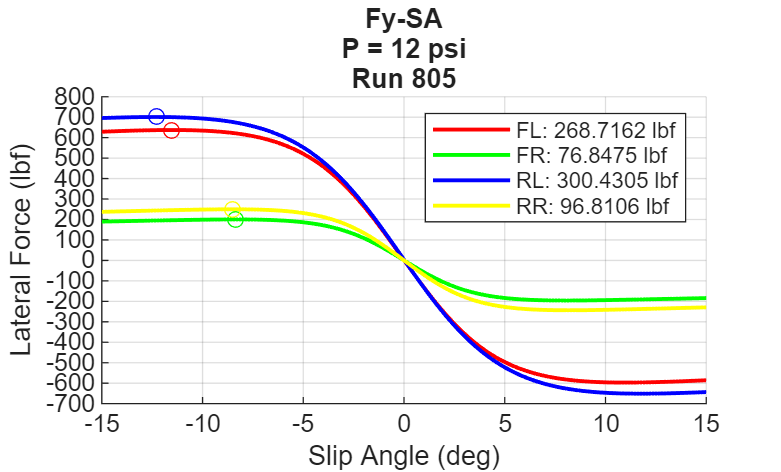

% INSTRUCTIONS:
% -> Based on either lat or long analysis, comment and uncomment plotting blocks
% -> For lateral analysis plots - USE LATERAL labelled blocks
% -> For longitudinal plots - USE LONGITUDINAL labelled blocks

% LATERAL: Lateral Force Vs Slip Angle
figure; hold on; grid on
plot(SA1, Fy1, 'r', 'LineWidth', 1.5)
plot(max_SA1, max_Fy1, ['', 'o', 'r'])
plot(SA2, Fy2, 'g', 'LineWidth', 1.5)
plot(max_SA2, max_Fy2, ['', 'o', 'g'])
plot(SA3, Fy3, 'b', 'LineWidth', 1.5)
plot(max_SA3, max_Fy3, ['', 'o', 'b'])
plot(SA4, Fy4, 'y', 'LineWidth', 1.5)
plot(max_SA4, max_Fy4, ['', 'o', 'y'])
ylim([-700,800]);
yticks(-700:(100):800);
title({'Fy-SA';  ['P = ' num2str(round((P1)/6894.76)) ' psi']; ['Run 805']})
xlabel('Slip Angle (deg)')
ylabel('Lateral Force (lbf)')
legend({ ...
    ['FL: ' num2str(Fz1_0) ' lbf']; '';...
    ['FR: ' num2str(Fz2_0) ' lbf']; '';...
    ['RL: ' num2str(Fz3_0) ' lbf']; '';...
    ['RR: ' num2str(Fz4_0) ' lbf']})

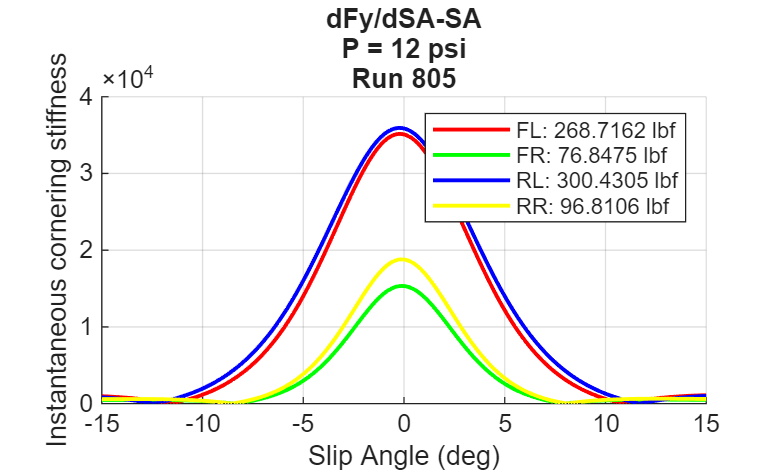


% LATERAL: Lateral Stiffness Vs Slip Angle
figure; hold on; grid on
plot(SA1, abs(ICS1), 'r', 'LineWidth', 1.5)
plot(SA2, abs(ICS2), 'g', 'LineWidth', 1.5)
plot(SA3, abs(ICS3), 'b', 'LineWidth', 1.5)
plot(SA4, abs(ICS4), 'y', 'LineWidth', 1.5)
% ylim([-600,600]);
% yticks(-600:(100):600);
title({['dFy/dSA-SA'];  ['P = ' num2str(round((P1)/6894.76)) ' psi']; ['Run 805']})
xlabel('Slip Angle (deg)')
ylabel('Instantaneous cornering stiffness')
legend({['FL: ' num2str(Fz1_0) ' lbf']; ['FR: ' num2str(Fz2_0) ' lbf']; ...
    ['RL: ' num2str(Fz3_0) ' lbf']; ['RR: ' num2str(Fz4_0) ' lbf']})

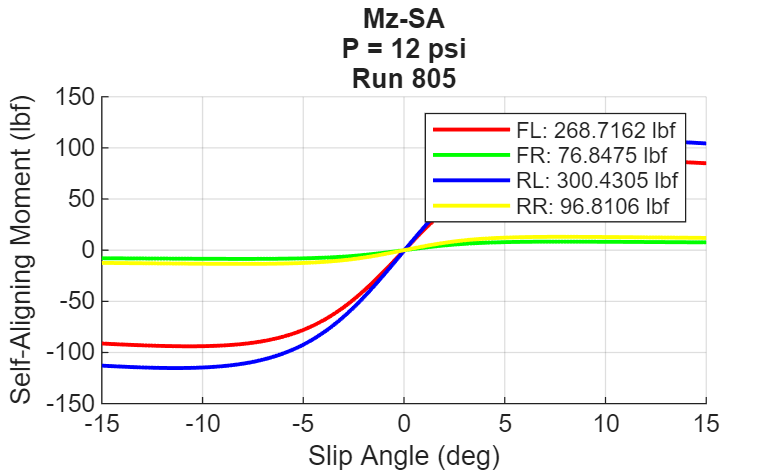


% LATERAL: Self Aligning Moment Vs Slip Angle
figure; hold on; grid on
plot(SA1, Mz1, 'r', 'LineWidth', 1.5)
plot(SA2, Mz2, 'g', 'LineWidth', 1.5)
plot(SA3, Mz3, 'b', 'LineWidth', 1.5)
plot(SA4, Mz4, 'y', 'LineWidth', 1.5)
% ylim([-600,600]);
% yticks(-600:(100):600);
title({'Mz-SA';  ['P = ' num2str(round((P1)/6894.76)) ' psi']; 'Run 805'})
xlabel('Slip Angle (deg)')
ylabel('Self-Aligning Moment (lbf)')
legend({['FL: ' num2str(Fz1_0) ' lbf']; ['FR: ' num2str(Fz2_0) ' lbf']; ...
    ['RL: ' num2str(Fz3_0) ' lbf']; ['RR: ' num2str(Fz4_0) ' lbf']})

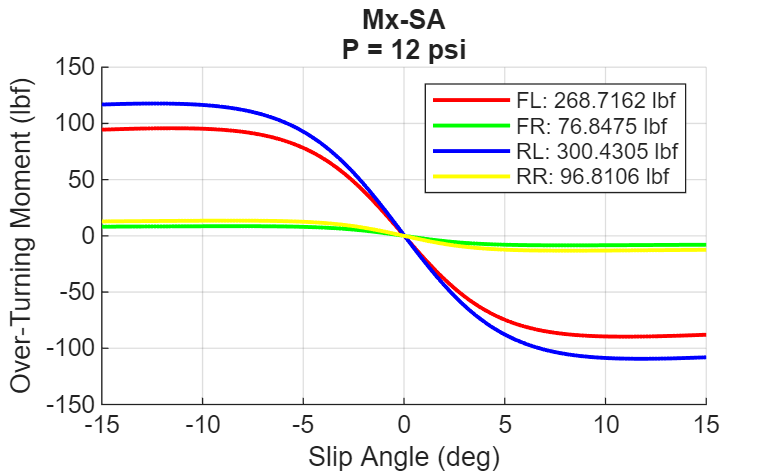


% LATERAL: Overturning Moment Vs Slip Angle
figure; hold on; grid on
plot(SA1, Mx1, 'r', 'LineWidth', 1.5)
plot(SA2, Mx2, 'g', 'LineWidth', 1.5)
plot(SA3, Mx3, 'b', 'LineWidth', 1.5)
plot(SA4, Mx4, 'y', 'LineWidth', 1.5)
% ylim([-600,600]);
% yticks(-600:(100):600);
title({'Mx-SA';  ['P = ' num2str(round((P1)/6894.76)) ' psi']})
xlabel('Slip Angle (deg)')
ylabel('Over-Turning Moment (lbf)')
legend({['FL: ' num2str(Fz1_0) ' lbf']; ['FR: ' num2str(Fz2_0) ' lbf']; ...
    ['RL: ' num2str(Fz3_0) ' lbf']; ['RR: ' num2str(Fz4_0) ' lbf']})

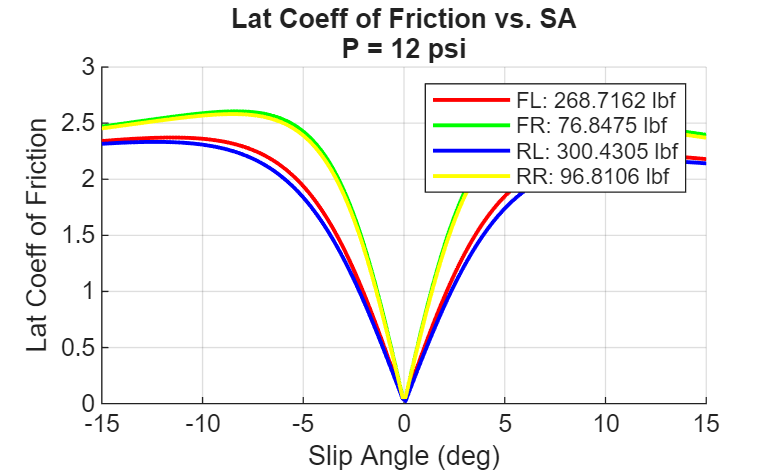


% LATERAL: Lateral Coef of Friction Vs Slip Angle
figure; hold on; grid on
plot(SA1, mu_lat1, 'r', 'LineWidth', 1.5)
plot(SA2, mu_lat2, 'g', 'LineWidth', 1.5)
plot(SA3, mu_lat3, 'b', 'LineWidth', 1.5)
plot(SA4, mu_lat4, 'y', 'LineWidth', 1.5)
% ylim([-600,600]);
% yticks(-600:(100):600);
title({'Lat Coeff of Friction vs. SA';  ['P = ' num2str(round((P1)/6894.76)) ' psi']})
xlabel('Slip Angle (deg)')
ylabel('Lat Coeff of Friction')
legend({['FL: ' num2str(Fz1_0) ' lbf']; ['FR: ' num2str(Fz2_0) ' lbf']; ...
    ['RL: ' num2str(Fz3_0) ' lbf']; ['RR: ' num2str(Fz4_0) ' lbf']})




%{
% % LONGITUDINAL: Long Coef of Friction Vs Long Slip
 figure; hold on; grid on
 plot(LS1, mu_long1, 'r', 'LineWidth', 1.5)
 plot(LS2, mu_long2, 'g', 'LineWidth', 1.5)
 plot(LS3, mu_long3, 'b', 'LineWidth', 1.5)
 plot(LS4, mu_long4, 'y', 'LineWidth', 1.5)
 ylim([-600,600]);
 yticks(-600:(100):600);
 title({'Long Coeff of Friction vs. SA';  ['P = ' num2str(round((P1)/6894.76)) ' psi']})
 xlabel('Longitudinal Slip (deg)')
 ylabel('Long Coeff of Friction')
 legend({['FL: ' num2str(Fz1_0) ' lbf']; ['FR: ' num2str(Fz2_0) ' lbf']; ...
     ['RL: ' num2str(Fz3_0) ' lbf']; ['RR: ' num2str(Fz4_0) ' lbf']})

% % LONGITUDINAL: Longitudinal Force Vs Long Slip
 figure; hold on; grid on
 plot(LS1, Fx1, 'r', 'LineWidth', 1.5)
 plot(LS2, Fx2, 'g', 'LineWidth', 1.5)
 plot(LS3, Fx3, 'b', 'LineWidth', 1.5)
 plot(LS4, Fx4, 'y', 'LineWidth', 1.5)
 ylim([-700,700]);
 yticks(-700:(100):700);
 title({['Fx-LS'];  ['P = ' num2str(round((P1)/6894.76)) ' psi']})
 xlabel('Longitudinal Slip')
 ylabel('Longitudinal Force (lbf)')
 legend({['FL: ' num2str(Fz1_0) ' lbf']; ['FR: ' num2str(Fz2_0) ' lbf']; ...
     ['RL: ' num2str(Fz3_0) ' lbf']; ['RR: ' num2str(Fz4_0) ' lbf']})
%}

% LATERAL: dFy/dSA vs SA Interpolation (ICS input)
% Input lateral stiffness value (ensure it's positive since you're using abs(ICS) for plotting)
target_stiffness = abs(1500);  % Input the target ICS here
target_SA = nan(1, 4);          % Stores slip angle for each tire, NaN if not reached
% Loop through each tire and find the closest slip angle for the target stiffness in the range [-20, 0]
for i = 1:4
    switch i
        case 1
            ICS = abs(ICS1);  
            SA = SA1;
        case 2
            ICS = abs(ICS2);
            SA = SA2;
        case 3
            ICS = abs(ICS3);
            SA = SA3;
        case 4
            ICS = abs(ICS4);
            SA = SA4;
    end    
    % Filter the data to include only the range -20 <= SA <= 0
    valid_idx = (SA >= -20 & SA <= 0);  % Logical index of valid range
    SA_filtered = SA(valid_idx);
    ICS_filtered = ICS(valid_idx);    
    % Check if the target stiffness is within the range of ICS_filtered
    if target_stiffness > max(ICS_filtered) || target_stiffness < min(ICS_filtered)
        fprintf('The target stiffness value (%.2f) is never reached for tire %d.\n', target_stiffness, i);
    else
        % Find the index where ICS_filtered is closest to the target stiffness
        [~, idx] = min(abs(ICS_filtered - target_stiffness));  % Find the index with the minimum difference        
        % Store the corresponding slip angle from the filtered data
        target_SA(i) = SA_filtered(idx);
    end
end
fprintf('Slip Angles corresponding to dFy/dSA = %.2f (in the range [-20, 0]):\n', target_stiffness);

Slip Angles corresponding to dFy/dSA = 1500.00 (in the range [-20, 0]):


for i = 1:4
    if isnan(target_SA(i))
        fprintf('Tire %d: Target stiffness never reached.\n', i);
    else
        fprintf('Tire %d: %.2f degrees\n', i, target_SA(i));
    end
end

Tire 1: -9.72 degrees
Tire 2: -6.11 degrees
Tire 3: -10.48 degrees
Tire 4: -6.41 degrees


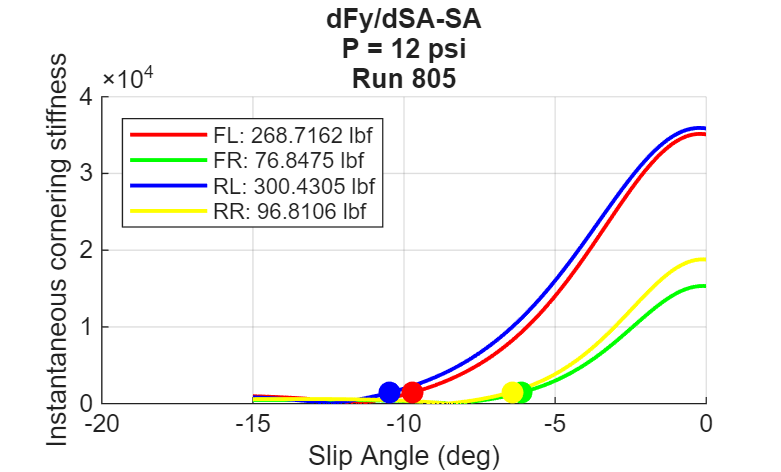

figure; hold on; grid on
plot(SA1, abs(ICS1), 'r', 'LineWidth', 1.5)
plot(SA2, abs(ICS2), 'g', 'LineWidth', 1.5)
plot(SA3, abs(ICS3), 'b', 'LineWidth', 1.5)
plot(SA4, abs(ICS4), 'y', 'LineWidth', 1.5)
if ~isnan(target_SA(1))
    plot(target_SA(1), target_stiffness, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r')
end
if ~isnan(target_SA(2))
    plot(target_SA(2), target_stiffness, 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g')
end
if ~isnan(target_SA(3))
    plot(target_SA(3), target_stiffness, 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b')
end
if ~isnan(target_SA(4))
    plot(target_SA(4), target_stiffness, 'yo', 'MarkerSize', 8, 'MarkerFaceColor', 'y')
end
xlim([-20, 0])
title({['dFy/dSA-SA'];  ['P = ' num2str(round((P1)/6894.76)) ' psi']; ['Run 805']})
xlabel('Slip Angle (deg)')
ylabel('Instantaneous cornering stiffness')
legend({['FL: ' num2str(Fz1_0) ' lbf']; ['FR: ' num2str(Fz2_0) ' lbf']; ...
    ['RL: ' num2str(Fz3_0) ' lbf']; ['RR: ' num2str(Fz4_0) ' lbf']}, 'Location', 'Best')

## Statistical Analysis

fprintf('Statistical Analysis')

Statistical Analysis

fprintf('NOTE: This version of the script calculates the slope of the Fy-SA plot at 0deg SA')

NOTE: This version of the script calculates the slope of the Fy-SA plot at 0deg SA

fprintf('NOTE: This script also calculates slope of linear region in lat CoF-SA plot')

NOTE: This script also calculates slope of linear region in lat CoF-SA plot

fprintf('Code functions can be found at script end')

Code functions can be found at script end

% INSTRUCTIONS:
% -> Based on either lat or long analysis, comment and uncomment function call blocks
% -> For lateral analysis functions - USE LATERAL labelled blocks
% -> For longitudinal functions - USE LONGITUDINAL labelled blocks


% LATERAL: Cornering Stiffness @ 0deg SA
[corneringStiffness_FL, corneringStiffness_FR, corneringStiffness_RL, corneringStiffness_RR] = calculateCorneringStiffness(SA1, Fy1, SA2, Fy2, SA3, Fy3, SA4, Fy4);
% Display results
fprintf('Cornering Stiffness at 0 deg SA:\n');

Cornering Stiffness at 0 deg SA:


fprintf('Front Left: %.3f lbf/deg\n', corneringStiffness_FL);

Front Left: -137.892 lbf/deg


fprintf('Front Right: %.3f lbf/deg\n', corneringStiffness_FR);

Front Right: -60.145 lbf/deg


fprintf('Rear Left: %.3f lbf/deg\n', corneringStiffness_RL);

Rear Left: -140.942 lbf/deg


fprintf('Rear Right: %.3f lbf/deg\n', corneringStiffness_RR);

Rear Right: -73.750 lbf/deg


% 
% LATERAL: Lateral Coefficient Slope Sensitivity
[slope_FL, slope_FR, slope_RL, slope_RR] = calculateLinearRegionSlope(SA1, mu_lat1, SA2, mu_lat2, SA3, mu_lat3, SA4, mu_lat4);
% Display results
fprintf('Slope of the Linear Region in the Lat CoF-SA plot:\n');

Slope of the Linear Region in the Lat CoF-SA plot:


fprintf('Front Left: %.3f\n', slope_FL);

Front Left: -0.464


fprintf('Front Right: %.3f\n', slope_FR);

Front Right: -0.642


fprintf('Rear Left: %.3f\n', slope_RL);

Rear Left: -0.430


fprintf('Rear Right: %.3f\n', slope_RR);

Rear Right: -0.630


% 
% LATERAL: Optimal/Peak Slip Angle
optimal_SA1 = findOptimalSA(SA1, Fy1);
optimal_SA2 = findOptimalSA(SA2, Fy2);
optimal_SA3 = findOptimalSA(SA3, Fy3);
optimal_SA4 = findOptimalSA(SA4, Fy4);
% Display results 
fprintf('The optimal Slip Angle (SA) is (FL): %.2f degrees\n', optimal_SA1);

The optimal Slip Angle (SA) is (FL): -11.53 degrees


fprintf('The optimal Slip Angle (SA) is (FR): %.2f degrees\n', optimal_SA2);

The optimal Slip Angle (SA) is (FR): -8.37 degrees


fprintf('The optimal Slip Angle (SA) is (RL): %.2f degrees\n', optimal_SA3);

The optimal Slip Angle (SA) is (RL): -12.29 degrees


fprintf('The optimal Slip Angle (SA) is (RR): %.2f degrees\n', optimal_SA4);

The optimal Slip Angle (SA) is (RR): -8.52 degrees



%{
% % LONGITUDINAL: Long Coefficient Sensitivity
 [slope_FL, slope_FR, slope_RL, slope_RR] = calculateLongCoFLinearRegionSlope(mu_long1, mu_long2, mu_long3, mu_long4, LS1, LS2, LS3, LS4); 
% % % Display results
  fprintf('Slope of the Linear Region in the Long CoF-Slip plot (from -1 to -0.4):\n');
  fprintf('Front Left: %.3f\n', slope_FL);
  fprintf('Front Right: %.3f\n', slope_FR);
  fprintf('Rear Left: %.3f\n', slope_RL);
  fprintf('Rear Right: %.3f\n', slope_RR);
%}

% LATERAL: Max Lateral Friction Coef
fprintf('Max Lateral Friction Coefficient: ')

Max Lateral Friction Coefficient: 

fprintf('Front Left Max Lateral Friction Coefficient = %.3f' ,muy1(1:1))

Front Left Max Lateral Friction Coefficient = 2.297

fprintf('Front Right Max Lateral Friction Coefficient = %.3f' ,muy2(1:1))

Front Right Max Lateral Friction Coefficient = 2.578

fprintf('Rear Left Max Lateral Friction Coefficient = %.3f' ,muy3(1:1))

Rear Left Max Lateral Friction Coefficient = 2.250

fprintf('Rear Right Max Lateral Friction Coefficient = %.3f' ,muy4(1:1))

Rear Right Max Lateral Friction Coefficient = 2.548



%{
% % % LONGITUDINAL: Max Longitudinal Friction Coef
 fprintf('Longitudinal Friction Coefficient: ')
 fprintf('Front Left Max Longitudinal Friction Coefficient = %.3f' ,mux1(1:1))
 fprintf('Front Right Max Longitudinal Friction Coefficient = %.3f' ,mux2(1:1))
 fprintf('Rear Left Max Longitudinal Friction Coefficient = %.3f' ,mux3(1:1))
 fprintf('Rear Right Max Longitudinal Friction Coefficient = %.3f' ,mux4(1:1))
%}
% LATERAL: Cornering Stiffness
fprintf('Cornering Stiffness: ')

Cornering Stiffness: 

fprintf('Cornering Stiffness at Fz of 50 lbf = %.3f' ,abs(Kya1(1:1)))

Cornering Stiffness at Fz of 50 lbf = 7904.544

fprintf('Cornering Stiffness at Fz of 150 lbf = %.3f' ,abs(Kya2(1:1)))

Cornering Stiffness at Fz of 150 lbf = 3448.809

fprintf('Cornering Stiffness at Fz of 250 lbf = %.3f' ,abs(Kya3(1:1)))

Cornering Stiffness at Fz of 250 lbf = 8079.603

fprintf('Cornering Stiffness at Fz of 224.809 lbf = %.3f' ,abs(Kya4(1:1)))

Cornering Stiffness at Fz of 224.809 lbf = 4228.506

## Additional Statistical Analysis -  Per Tire

% INSTRUCTIONS:
% -> DO NOT CHANGE THIS PORTION OF THE CODE UNLESS EXPLICIT PARMETERS
% REQUIRED

% FL - Tire 1
fprintf('Tire 1: ')

Tire 1: 

fprintf('FL Max Lateral Force = %.3f' ,max(Fy1))

FL Max Lateral Force = 637.308

fprintf('FL Range of Max Lateral Force = %.3f' ,(max(Fy1)) - abs(min(Fy1)))

FL Range of Max Lateral Force = 40.285

fprintf('FL Standard Deviation of Lateral Force = %.3f' ,std2(Fy1))

FL Standard Deviation of Lateral Force = 526.255

fprintf('FL Max Lateral CoF = %.3f' ,max(mu_lat1))

FL Max Lateral CoF = 2.372

fprintf('FL Range of Lat CoF = %.3f' ,(max(mu_lat1))-abs(min(mu_lat1)))

FL Range of Lat CoF = 2.339

fprintf('FL Standard Deviation of Max CoF = %.3f', std2(mu_lat1))

FL Standard Deviation of Max CoF = 0.631

fprintf('FL Max Long Force = %.3f' ,max(Fx1))

FL Max Long Force = 0.000

fprintf('FL Max Long CoF = %.3f' ,max(mu_long1))

FL Max Long CoF = 0.000

fprintf('FL Max Mz = %.3f' ,max(Mz1))

FL Max Mz = 88.127

fprintf('FL Max Mx = %.3f' ,max(Mx1))

FL Max Mx = 95.704

fprintf('FL Max Instanteous Cornering Stiffness = %.3f' ,max(ICS1))

FL Max Instanteous Cornering Stiffness = 1093.214


% FR - Tire 2
fprintf('Tire 2: ')

Tire 2: 

fprintf('FR Max Lateral Force = %.3f' ,max(Fy2))

FR Max Lateral Force = 200.219

fprintf('FR Range of Max Lateral Force = %.3f' ,(max(Fy2)) - abs(min(Fy2)))

FR Range of Max Lateral Force = 4.284

fprintf('FR Standard Deviation of Lateral Force = %.3f' ,std2(Fy2))

FR Standard Deviation of Lateral Force = 175.139

fprintf('FR Max Lateral CoF = %.3f' ,max(mu_lat2))

FR Max Lateral CoF = 2.605

fprintf('FR Range of Lat CoF = %.3f' ,(max(mu_lat2))-abs(min(mu_lat2)))

FR Range of Lat CoF = 2.550

fprintf('FR Standard Deviation of Max CoF = %.3f', std2(mu_lat2))

FR Standard Deviation of Max CoF = 0.631

fprintf('FR Max Long Force = %.3f' ,max(Fx2))

FR Max Long Force = 0.000

fprintf('FR Max Long CoF = %.3f' ,max(mu_long2))

FR Max Long CoF = 0.000

fprintf('FR Max Mz = %.3f' ,max(Mz2))

FR Max Mz = 8.335

fprintf('FR Max Mx = %.3f' ,max(Mx2))

FR Max Mx = 8.598

fprintf('FR Max Instanteous Cornering Stiffness = %.3f' ,max(ICS2))

FR Max Instanteous Cornering Stiffness = 526.278


% RL - Tire 3
fprintf('Tire 3: ')

Tire 3: 

fprintf('RL Max Lateral Force = %.3f' ,max(Fy3))

RL Max Lateral Force = 700.915

fprintf('RL Range of Max Lateral Force = %.3f' ,(max(Fy3)) - abs(min(Fy3)))

RL Range of Max Lateral Force = 49.718

fprintf('RL Standard Deviation of Lateral Force = %.3f' ,std2(Fy3))

RL Standard Deviation of Lateral Force = 569.220

fprintf('RL Max Lateral CoF = %.3f' ,max(mu_lat3))

RL Max Lateral CoF = 2.333

fprintf('RL Range of Lat CoF = %.3f' ,(max(mu_lat3))-abs(min(mu_lat3)))

RL Range of Lat CoF = 2.309

fprintf('RL Standard Deviation of Max CoF = %.3f', std2(mu_lat3))

RL Standard Deviation of Max CoF = 0.631

fprintf('RL Max Long Force = %.3f' ,max(Fx3))

RL Max Long Force = 0.000

fprintf('RL Max Long CoF = %.3f' ,max(mu_long3))

RL Max Long CoF = 0.000

fprintf('RL Max Mz = %.3f' ,max(Mz3))

RL Max Mz = 107.211

fprintf('RL Max Mx = %.3f' ,max(Mx3))

RL Max Mx = 117.678

fprintf('RL Max Instanteous Cornering Stiffness = %.3f' ,max(ICS3))

RL Max Instanteous Cornering Stiffness = 991.718


% RR - Tire 4
fprintf('Tire 4: ')

Tire 4: 

fprintf('RR Max Lateral Force = %.3f' ,max(Fy4))

RR Max Lateral Force = 249.877

fprintf('RR Range of Max Lateral Force = %.3f' ,(max(Fy4)) - abs(min(Fy4)))

RR Range of Max Lateral Force = 6.346

fprintf('RR Standard Deviation of Lateral Force = %.3f' ,std2(Fy4))

RR Standard Deviation of Lateral Force = 217.884

fprintf('RR Max Lateral CoF = %.3f' ,max(mu_lat4))

RR Max Lateral CoF = 2.581

fprintf('RR Range of Lat CoF = %.3f' ,(max(mu_lat4))-abs(min(mu_lat4)))

RR Range of Lat CoF = 2.524

fprintf('RR Standard Deviation of Max CoF = %.3f', std2(mu_lat4))

RR Standard Deviation of Max CoF = 0.629

fprintf('RR Max Long Force = %.3f' ,max(Fx4))

RR Max Long Force = 0.000

fprintf('RR Max Long CoF = %.3f' ,max(mu_long4))

RR Max Long CoF = 0.000

fprintf('RR Max Mz = %.3f' ,max(Mz4))

RR Max Mz = 13.047

fprintf('RR Max Mx = %.3f' ,max(Mx4))

RR Max Mx = 13.519

fprintf('RR Max Instanteous Cornering Stiffness = %.3f' ,max(ICS4))

RR Max Instanteous Cornering Stiffness = 643.792

%%%%%%%%%%%%% Tire Rate Calculation %%%%%%%%%%%%%%%%

Fz_1 = ones(nPoints,1)*200;

Unrecognized function or variable 'nPoints'.

Fz_2 = ones(nPoints,1)*250;
Fz_3 = ones(nPoints,1)*300;
Fz_4 = ones(nPoints,1)*350;
Fz_5 = ones(nPoints,1)*400;
Fz_6 = ones(nPoints,1)*450;
Fz_7 = ones(nPoints,1)*500;
Fz_8 = ones(nPoints,1)*550;
Fz_9 = ones(nPoints,1)*600;
Fz_10 = ones(nPoints,1)*650;
Fz_11 = ones(nPoints,1)*700;
Fz_12 = ones(nPoints,1)*750;
Fz_13 = ones(nPoints,1)*800;
Fz_14 = ones(nPoints,1)*850;
Fz_15 = ones(nPoints,1)*900;
Fz_16 = ones(nPoints,1)*950;
Fz_17 = ones(nPoints,1)*1000;
Fz_18 = ones(nPoints,1)*1050;
Fz_19 = ones(nPoints,1)*1100;
Fz_20 = ones(nPoints,1)*1150;
Fz_21 = ones(nPoints,1)*1200;
Fz_22 = ones(nPoints,1)*1250;
Fz_23 = ones(nPoints,1)*1300;
Fz_24 = ones(nPoints,1)*1350;
Fz_25 = ones(nPoints,1)*1400;
Fz_26 = ones(nPoints,1)*1450;
Fz_27 = ones(nPoints,1)*1500;
Fz_28 = ones(nPoints,1)*1550;
Fz_29 = ones(nPoints,1)*1600;
Fz_30 = ones(nPoints,1)*1650;
Fz_31 = ones(nPoints,1)*1700;
Fz_32 = ones(nPoints,1)*1750;
Fz_33 = ones(nPoints,1)*1800;
Fz_34 = ones(nPoints,1)*1850;
Fz_35 = ones(nPoints,1)*1900;
Fz_36 = ones(nPoints,1)*1950;
Fz_37 = ones(nPoints,1)*2000;
Fz_38 = ones(nPoints,1)*2050;
Fz_39 = ones(nPoints,1)*2100;
Fz_40 = ones(nPoints,1)*2150;
Fz_41 = ones(nPoints,1)*2200;


input_1 = [Fz_1 kappa alpha gamma phit Vx P];
input_2 = [Fz_2 kappa alpha gamma phit Vx P];
input_3 = [Fz_3 kappa alpha gamma phit Vx P];
input_4 = [Fz_4 kappa alpha gamma phit Vx P];
input_5 = [Fz_5 kappa alpha gamma phit Vx P];
input_6 = [Fz_6 kappa alpha gamma phit Vx P];
input_7 = [Fz_7 kappa alpha gamma phit Vx P];
input_8 = [Fz_8 kappa alpha gamma phit Vx P];
input_9 = [Fz_9 kappa alpha gamma phit Vx P];
input_10 = [Fz_10 kappa alpha gamma phit Vx P];
input_11 = [Fz_11 kappa alpha gamma phit Vx P];
input_12 = [Fz_12 kappa alpha gamma phit Vx P];
input_13 = [Fz_13 kappa alpha gamma phit Vx P];
input_14 = [Fz_14 kappa alpha gamma phit Vx P];
input_15 = [Fz_15 kappa alpha gamma phit Vx P];
input_16 = [Fz_16 kappa alpha gamma phit Vx P];
input_17 = [Fz_17 kappa alpha gamma phit Vx P];
input_18 = [Fz_18 kappa alpha gamma phit Vx P];
input_19 = [Fz_19 kappa alpha gamma phit Vx P];
input_20 = [Fz_20 kappa alpha gamma phit Vx P];
input_21 = [Fz_21 kappa alpha gamma phit Vx P];
input_22 = [Fz_22 kappa alpha gamma phit Vx P];
input_23 = [Fz_23 kappa alpha gamma phit Vx P];
input_24 = [Fz_24 kappa alpha gamma phit Vx P];
input_25 = [Fz_25 kappa alpha gamma phit Vx P];
input_26 = [Fz_26 kappa alpha gamma phit Vx P];
input_27 = [Fz_27 kappa alpha gamma phit Vx P];
input_28 = [Fz_28 kappa alpha gamma phit Vx P];
input_29 = [Fz_29 kappa alpha gamma phit Vx P];
input_30 = [Fz_30 kappa alpha gamma phit Vx P];
input_31 = [Fz_31 kappa alpha gamma phit Vx P];
input_32 = [Fz_32 kappa alpha gamma phit Vx P];
input_33 = [Fz_33 kappa alpha gamma phit Vx P];
input_34 = [Fz_34 kappa alpha gamma phit Vx P];
input_35 = [Fz_35 kappa alpha gamma phit Vx P];
input_36 = [Fz_36 kappa alpha gamma phit Vx P];
input_37 = [Fz_37 kappa alpha gamma phit Vx P];
input_38 = [Fz_38 kappa alpha gamma phit Vx P];
input_39 = [Fz_39 kappa alpha gamma phit Vx P];
input_40 = [Fz_40 kappa alpha gamma phit Vx P];
input_41 = [Fz_41 kappa alpha gamma phit Vx P];

output_1 = mfeval(TIRfile, input_1, useMode);
output_2 = mfeval(TIRfile, input_2, useMode);
output_3 = mfeval(TIRfile, input_3, useMode);
output_4 = mfeval(TIRfile, input_4, useMode);
output_5 = mfeval(TIRfile, input_5, useMode);
output_6 = mfeval(TIRfile, input_6, useMode);
output_7 = mfeval(TIRfile, input_7, useMode);
output_8 = mfeval(TIRfile, input_8, useMode);
output_9 = mfeval(TIRfile, input_9, useMode);
output_10 = mfeval(TIRfile, input_10, useMode);
output_11 = mfeval(TIRfile, input_11, useMode);
output_12 = mfeval(TIRfile, input_12, useMode);
output_13 = mfeval(TIRfile, input_13, useMode);
output_14 = mfeval(TIRfile, input_14, useMode);
output_15 = mfeval(TIRfile, input_15, useMode);
output_16 = mfeval(TIRfile, input_16, useMode);
output_17 = mfeval(TIRfile, input_17, useMode);
output_18 = mfeval(TIRfile, input_18, useMode);
output_19 = mfeval(TIRfile, input_19, useMode);
output_20 = mfeval(TIRfile, input_20, useMode);
output_21 = mfeval(TIRfile, input_21, useMode);
output_22 = mfeval(TIRfile, input_22, useMode);
output_23 = mfeval(TIRfile, input_23, useMode);
output_24 = mfeval(TIRfile, input_24, useMode);
output_25 = mfeval(TIRfile, input_25, useMode);
output_26 = mfeval(TIRfile, input_26, useMode);
output_27 = mfeval(TIRfile, input_27, useMode);
output_28 = mfeval(TIRfile, input_28, useMode);
output_29 = mfeval(TIRfile, input_29, useMode);
output_30 = mfeval(TIRfile, input_30, useMode);
output_31 = mfeval(TIRfile, input_31, useMode);
output_32 = mfeval(TIRfile, input_32, useMode);
output_33 = mfeval(TIRfile, input_33, useMode);
output_34 = mfeval(TIRfile, input_34, useMode);
output_35 = mfeval(TIRfile, input_35, useMode);
output_36 = mfeval(TIRfile, input_36, useMode);
output_37 = mfeval(TIRfile, input_37, useMode);
output_38 = mfeval(TIRfile, input_38, useMode);
output_39 = mfeval(TIRfile, input_39, useMode);
output_40 = mfeval(TIRfile, input_40, useMode);
output_41 = mfeval(TIRfile, input_41, useMode);

Fz = zeros(41,1);
Fz(1,1) = output_1(1,3)*0.224809;
Fz(2,1) = output_2(1,3)*0.224809;
Fz(3,1) = output_3(1,3)*0.224809;
Fz(4,1) = output_4(1,3)*0.224809;
Fz(5,1) = output_5(1,3)*0.224809;
Fz(6,1) = output_6(1,3)*0.224809;
Fz(7,1) = output_7(1,3)*0.224809;
Fz(8,1) = output_8(1,3)*0.224809;
Fz(9,1) = output_9(1,3)*0.224809;
Fz(10,1) = output_10(1,3)*0.224809;
Fz(11,1) = output_11(1,3)*0.224809;
Fz(12,1) = output_12(1,3)*0.224809;
Fz(13,1) = output_13(1,3)*0.224809;
Fz(14,1) = output_14(1,3)*0.224809;
Fz(15,1) = output_15(1,3)*0.224809;
Fz(16,1) = output_16(1,3)*0.224809;
Fz(17,1) = output_17(1,3)*0.224809;
Fz(18,1) = output_18(1,3)*0.224809;
Fz(19,1) = output_19(1,3)*0.224809;
Fz(20,1) = output_20(1,3)*0.224809;
Fz(21,1) = output_21(1,3)*0.224809;
Fz(22,1) = output_22(1,3)*0.224809;
Fz(23,1) = output_23(1,3)*0.224809;
Fz(24,1) = output_24(1,3)*0.224809;
Fz(25,1) = output_25(1,3)*0.224809;
Fz(26,1) = output_26(1,3)*0.224809;
Fz(27,1) = output_27(1,3)*0.224809;
Fz(28,1) = output_28(1,3)*0.224809;
Fz(29,1) = output_29(1,3)*0.224809;
Fz(30,1) = output_30(1,3)*0.224809;
Fz(31,1) = output_31(1,3)*0.224809;
Fz(32,1) = output_32(1,3)*0.224809;
Fz(33,1) = output_33(1,3)*0.224809;
Fz(34,1) = output_34(1,3)*0.224809;
Fz(35,1) = output_35(1,3)*0.224809;
Fz(36,1) = output_36(1,3)*0.224809;
Fz(37,1) = output_37(1,3)*0.224809;
Fz(38,1) = output_38(1,3)*0.224809;
Fz(39,1) = output_39(1,3)*0.224809;
Fz(40,1) = output_40(1,3)*0.224809;
Fz(41,1) = output_41(1,3)*0.224809;

ICS = zeros(41,1);
ICS(1,1) = output_1(1,29);
ICS(2,1) = output_2(1,29);
ICS(3,1) = output_3(1,29);
ICS(4,1) = output_4(1,29);
ICS(5,1) = output_5(1,29);
ICS(6,1) = output_6(1,29);
ICS(7,1) = output_7(1,29);
ICS(8,1) = output_8(1,29);
ICS(9,1) = output_9(1,29);
ICS(10,1) = output_10(1,29);
ICS(11,1) = output_11(1,29);
ICS(12,1) = output_12(1,29);
ICS(13,1) = output_13(1,29);
ICS(14,1) = output_14(1,29);
ICS(15,1) = output_15(1,29);
ICS(16,1) = output_16(1,29);
ICS(17,1) = output_17(1,29);
ICS(18,1) = output_18(1,29);
ICS(19,1) = output_19(1,29);
ICS(20,1) = output_20(1,29);
ICS(21,1) = output_21(1,29);
ICS(22,1) = output_22(1,29);
ICS(23,1) = output_23(1,29);
ICS(24,1) = output_24(1,29);
ICS(25,1) = output_25(1,29);
ICS(26,1) = output_26(1,29);
ICS(27,1) = output_27(1,29);
ICS(28,1) = output_28(1,29);
ICS(29,1) = output_29(1,29);
ICS(30,1) = output_30(1,29);
ICS(31,1) = output_31(1,29);
ICS(32,1) = output_32(1,29);
ICS(33,1) = output_33(1,29);
ICS(34,1) = output_34(1,29);
ICS(35,1) = output_35(1,29);
ICS(36,1) = output_36(1,29);
ICS(37,1) = output_37(1,29);
ICS(38,1) = output_38(1,29);
ICS(39,1) = output_39(1,29);
ICS(40,1) = output_40(1,29);
ICS(41,1) = output_41(1,29);


% LoadedR = zeros(22,1);
% LoadedR(1,1) = output_1(1,20);
% LoadedR(2,1) = output_2(1,20);
% LoadedR(3,1) = output_3(1,20);
% LoadedR(4,1) = output_4(1,20);
% LoadedR(5,1) = output_5(1,20);
% LoadedR(6,1) = output_6(1,20);
% LoadedR(7,1) = output_7(1,20);
% LoadedR(8,1) = output_8(1,20);
% LoadedR(9,1) = output_9(1,20);
% LoadedR(10,1) = output_10(1,20);
% LoadedR(11,1) = output_11(1,20);
% LoadedR(12,1) = output_12(1,20);
% LoadedR(13,1) = output_13(1,20);
% LoadedR(14,1) = output_14(1,20);
% LoadedR(15,1) = output_15(1,20);
% LoadedR(16,1) = output_16(1,20);
% LoadedR(17,1) = output_17(1,20);
% LoadedR(18,1) = output_18(1,20);
% LoadedR(19,1) = output_19(1,20);
% LoadedR(20,1) = output_20(1,20);
% LoadedR(21,1) = output_21(1,20);
% LoadedR(22,1) = output_22(1,20);
% 
% 
% dFzdRL = polyfit(LoadedR, Fz,1);
% TireRate = dFzdRL(1,1)
% figure; hold on; grid on
% plot(LoadedR, Fz, 'r', 'LineWidth', 1.5)
% title({['Fz-RL'];  ['P = ' num2str(round((P1)/6894.76)) ' psi']})
% xlabel('Loaded Radius')
% ylabel('Normal Force (lbf)')
% % legend({['FL: ' num2str(Fz1_FL) ' lbf'];

figure; hold on; grid on
plot(Fz, ICS, 'r', 'LineWidth', 1.5)
title({['ICS-Fz'];  ['P = ' num2str(round((P1)/6894.76)) ' psi']})
xlabel('Normal Force (lbf)')
ylabel('Instantaneous Cornering Stiffness')

% figure
% subplot(2,2,1)
% plot(SA, Fy)
% grid on
% title('Fy-SA')
% xlabel('Slip Angle (deg)')
% ylabel('Lateral Force (N)')
% 
% subplot(2,2,2)
% plot(SA, Mz)
% grid on
% title('Mz-SA')
% xlabel('Slip Angle (deg)')
% ylabel('Self aligning moment (Nm)')
% 
% subplot(2,2,3)
% plot(SA, t)
% grid on
% title('t-SA')
% xlabel('Slip Angle (deg)')
% ylabel('pneumatic trail (m)')
% 
% subplot(2,2,4)
% plot(SA, Mx)
% grid on
% title('Mx-SA')
% xlabel('Slip Angle (deg)')
% ylabel('Overturning moment (Nm)')



## Defining Functions:

function [corneringStiffness_FL, corneringStiffness_FR, corneringStiffness_RL, corneringStiffness_RR] = calculateCorneringStiffness(SA1, Fy1, SA2, Fy2, SA3, Fy3, SA4, Fy4)
    % Find the index of the slip angle closest to 0
    [~, idx1] = min(abs(SA1));
    [~, idx2] = min(abs(SA2));
    [~, idx3] = min(abs(SA3));
    [~, idx4] = min(abs(SA4));
    
    % Calculate the cornering stiffness using central difference method
    corneringStiffness_FL = (Fy1(idx1+1) - Fy1(idx1-1)) / (SA1(idx1+1) - SA1(idx1-1));
    corneringStiffness_FR = (Fy2(idx2+1) - Fy2(idx2-1)) / (SA2(idx2+1) - SA2(idx2-1));
    corneringStiffness_RL = (Fy3(idx3+1) - Fy3(idx3-1)) / (SA3(idx3+1) - SA3(idx3-1));
    corneringStiffness_RR = (Fy4(idx4+1) - Fy4(idx4-1)) / (SA4(idx4+1) - SA4(idx4-1));
end

function [slope_FL, slope_FR, slope_RL, slope_RR] = calculateLinearRegionSlope(SA1, mu_lat1, SA2, mu_lat2, SA3, mu_lat3, SA4, mu_lat4)
    % Define the linear region boundaries
    linearRegionMinSA = -3; % Lower bound of the linear region
    linearRegionMaxSA = 0;  % Upper bound of the linear region

    % Identify the indices for the linear region
    idx1 = find(SA1 >= linearRegionMinSA & SA1 <= linearRegionMaxSA);
    idx2 = find(SA2 >= linearRegionMinSA & SA2 <= linearRegionMaxSA);
    idx3 = find(SA3 >= linearRegionMinSA & SA3 <= linearRegionMaxSA);
    idx4 = find(SA4 >= linearRegionMinSA & SA4 <= linearRegionMaxSA);

    % Perform linear regression on the identified linear region
    p1 = polyfit(SA1(idx1), mu_lat1(idx1), 1);
    p2 = polyfit(SA2(idx2), mu_lat2(idx2), 1);
    p3 = polyfit(SA3(idx3), mu_lat3(idx3), 1);
    p4 = polyfit(SA4(idx4), mu_lat4(idx4), 1);

    % Extract the slope (first coefficient) from the linear fit
    slope_FL = p1(1);
    slope_FR = p2(1);
    slope_RL = p3(1);
    slope_RR = p4(1);
end

function [slope_FL, slope_FR, slope_RL, slope_RR] = calculateLongCoFLinearRegionSlope(mu_long1, mu_long2, mu_long3, mu_long4, LS1, LS2, LS3, LS4)
    % Define the longitudinal slip range boundaries
    slipStart = -1; % Starting slip value of the range
    slipEnd = -0.4; % Ending slip value of the range

    % Find indices within the specified slip range for each tire
    idx1 = find(LS1 >= slipStart & LS1 <= slipEnd);
    idx2 = find(LS2 >= slipStart & LS2 <= slipEnd);
    idx3 = find(LS3 >= slipStart & LS3 <= slipEnd);
    idx4 = find(LS4 >= slipStart & LS4 <= slipEnd);

    % Perform linear regression on the identified longitudinal slip range
    p1 = polyfit(LS1(idx1), mu_long1(idx1), 1);
    p2 = polyfit(LS2(idx2), mu_long2(idx2), 1);
    p3 = polyfit(LS3(idx3), mu_long3(idx3), 1);
    p4 = polyfit(LS4(idx4), mu_long4(idx4), 1);

    % Extract the slope (first coefficient) from the linear fit
    slope_FL = p1(1);
    slope_FR = p2(1);
    slope_RL = p3(1);
    slope_RR = p4(1);
end

function optimal_SA = findOptimalSA(SA, Fy)
    % Ensure input data is sorted by SA (if not already)
    [SA, sortIdx] = sort(SA);
    Fy = Fy(sortIdx);
    
    % Find the index of the maximum Fy
    [~, maxIdx] = max(Fy);
    
    % Return the SA corresponding to the maximum Fy
    optimal_SA = SA(maxIdx);
end